# Reto - Entrega Final

Fernanda Reyes Martínez - A01637163

Karen Corona Espinoza - A01642461

Diego Ivan Morales Gallardo - A01643382

Joel Antonio Palomera Corona - A01644003

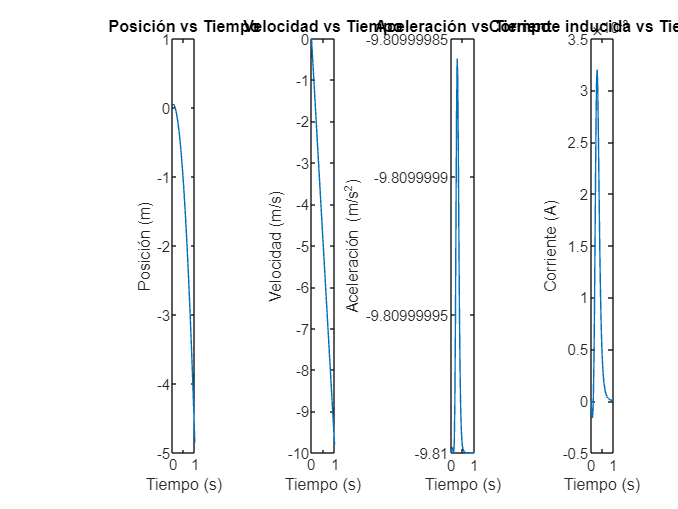

clearvars
clc
clf
% Constantes
% Permeabilidad del vacío
mu0 = 4 * pi * 1e-7;
% Gravedad
g = 9.81;
% Momento magnético del dipolo
M = 2.5;

% Valores cambiantes
% Radio de la espira 
r = 0.5;
% Número de vueltas
N = 30;
% Resistencia 
R = 0.7;
% Masa
m = 0.65;

% Constantes para ecuaciones del movimineto
km = (9 * (mu0 ^ 2) * (M ^ 2) * (r ^ 4) * (N ^ 2)) / (4 * m * R);
km2 = (3 * mu0 * M * N * (r ^ 2)) / (2 * R);

% Condiciones iniciales
v0 = 0;
z0 = 0.05;
tt = 1;

% Función aceleración
A = @(z, v) - (km * (z.^2)./ ((r.^2 + z.^2).^5)).* v - g;

% Sistema de ecuaciones diferencial dydt
dydt = @(t, y) [y(2); A(y(1), y(2))];

% Sistema de ecuaciones diferenciales ODE
[t, y] = ode45(dydt, [0 tt], [z0; v0]);

% Calcular la posición (z), la velocidad (v), la aceleración (a), la fuerza (f) y la corriente inducida (I)
z = y(:, 1);
v = y(:, 2);
a = A(z, v);
f = m * a;
I = km.* z.* v./((r * r + z.* z).^ (2.5));

% Generar gráficas
subplot(1, 4, 1);
plot(t, z);
title('Posición vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Posición (m)');

subplot(1, 4, 2);
plot(t, v);
title('Velocidad vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');

subplot(1, 4, 3);
plot(t, a);
title('Aceleración vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');

subplot(1, 4, 4);
plot(t, I);
title('Corriente inducida vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Corriente (A)');